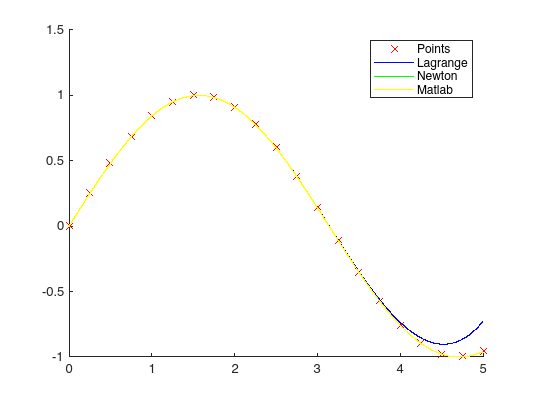

% clear variables
clear

% disable bad polynomial warning
warning("off", "MATLAB:polyfit:RepeatedPointsOrRescale")


startX = 0;
stepX = 0.25;
endX = 5;

X = startX:stepX:endX;

Y = sin(X);

% X = [1, 2, 3, 50];
% Y = [4, 5, 6, 70];


n = length(X);


% clear plot and hold
clf
hold on


% plot points
plot(X, Y, "xr")


stepT = 0.001;

t = startX:stepT:endX;


% Lagrange
L = lagrange(X, Y);
Ly = polyval(L, t);
plot(t, Ly, "b")


% Newton
N = newton(X, Y);
Ny = polyval(N, t);
plot(t, Ny, "g")


% Matlab
M = polyfit(X, Y, n-1);
My = polyval(M, t);
plot(t, My, "y")


% add legend
legend("Points", "Lagrange", "Newton", "Matlab")



% plot all versions one by one

figure
hold on
fprintf("Lagrange")

Lagrange

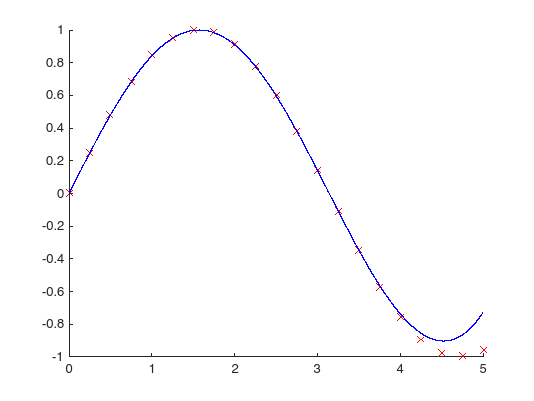

plot(X, Y, "xr")
plot(t, Ly, "b")


figure
hold on
fprintf("Newton")

Newton

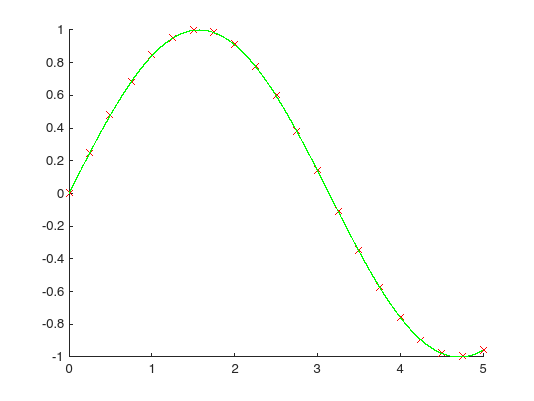

plot(X, Y, "xr")
plot(t, Ny, "g")


figure
hold on
fprintf("Matlab")

Matlab

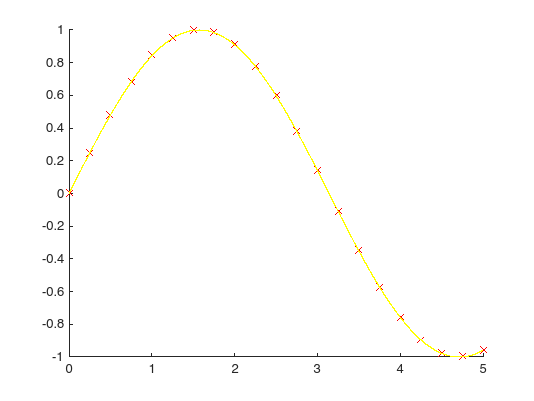

plot(X, Y, "xr")
plot(t, My, "y")



% print coeffitients
for i = 1:n
    fprintf("L(%d) = %.20f, N(%d) = %.20f, M(%d) = %.20f\n", i, L(i), i, N(i), i, M(i))
end

L(1) = -0.00000000000000003054, N(1) = 0.00000000000000000017, M(1) = 0.00000000000000008643
L(2) = 0.00000000000000077786, N(2) = -0.00000000000000000294, M(2) = -0.00000000000000434775
L(3) = 0.00000000000000003963, N(3) = -0.00000000000000015064, M(3) = 0.00000000000010169474
L(4) = 0.00000000000028415725, N(4) = 0.00000000000000471076, M(4) = -0.00000000000147064877
L(5) = -0.00000000000175086334, N(5) = -0.00000000000001471169, M(5) = 0.00000000001477658669
L(6) = -0.00000000000209626760, N(6) = -0.00000000000069055255, M(6) = -0.00000000010960005234
L(7) = -0.00000000010493206304, N(7) = -0.00000000000022395678, M(7) = 0.00000000060971295149
L(8) = 0.00000000131162991579, N(8) = 0.00000000016074488572, M(8) = -0.00000000249402208069
L(9) = -0.00000000332759952926, N(9) = 0.00000000000223529085, M(9) = 0.00000000910014362554
L(10) = -0.00000001850614239629, N(10) = -0.00000002506558685461, M(10) = -0.00000004978440007560
L(11) = 0.00000000398796373702, N(11) = 0.000000000044895476